# ME 5714: Take Home Final

Sam Kramer

ME 5714: Digital Signal Processing

Dr. Wicks

%{
    This is the code for the final take home exam for ME5714: DSP. This
    will be due on May 9th, at 11:59 pm.

    Sam Kramer
    May 2nd, 2023
%}

% --Setup
    clear; clc; format compact; close all;

### Problem Description

Note: I have not explicitly ask for plots and comparisons etc. Its assumed to present this information as part of your answer for each question. Each question is worth 33 points

1. One of the first assignments was to estimate heart rate variability. Each of you used the time difference between the peaks of the EKG signal. If we consider the average heart rate in the signal a carrier frequency, then the variability is the frequency variation around the average frequency, frequency modulated. We have a MatLab m-file (fmdemod) that might help. Also, you might consider fmmod. m to assist in building a test case to explore FM signals before applying to the EKG data Lets assume that the variability is limited to +/- 10% about the average frequency. Build a bandpass filter (Butterworth, cutoffs at +/- 15% of center frequency, 4th order) to create the input signal.

a) Build a known signal ie an FM signal, known carrier frequency and a known modulation frequency with the goal of validating your process.

b) Pass your known signal through your system. Discuss the output, ie is the demod signal the signal you put in?

c) Assuming that your demod process works, process the EKG data provided.

2. Given the image of the road, select the center row vector. Convert the vector into the frequency domain. Use grayscale image.

a) Find the derivative of the vector in the frequency domain.

b) Find the second derivative

3. Image 2 is the type of images often used for training OCR algorithms. Use a 5X5 smoothing matrix as discussed in class to attempt to smooth the image

a) Convolve the smoothing matrix with the image.

b) Convert the image and the smoothing matrix into the frequency domain, multiply to form the smoothed image

c) Compare the two images after smoothing

## Question 1: HRV Revisit

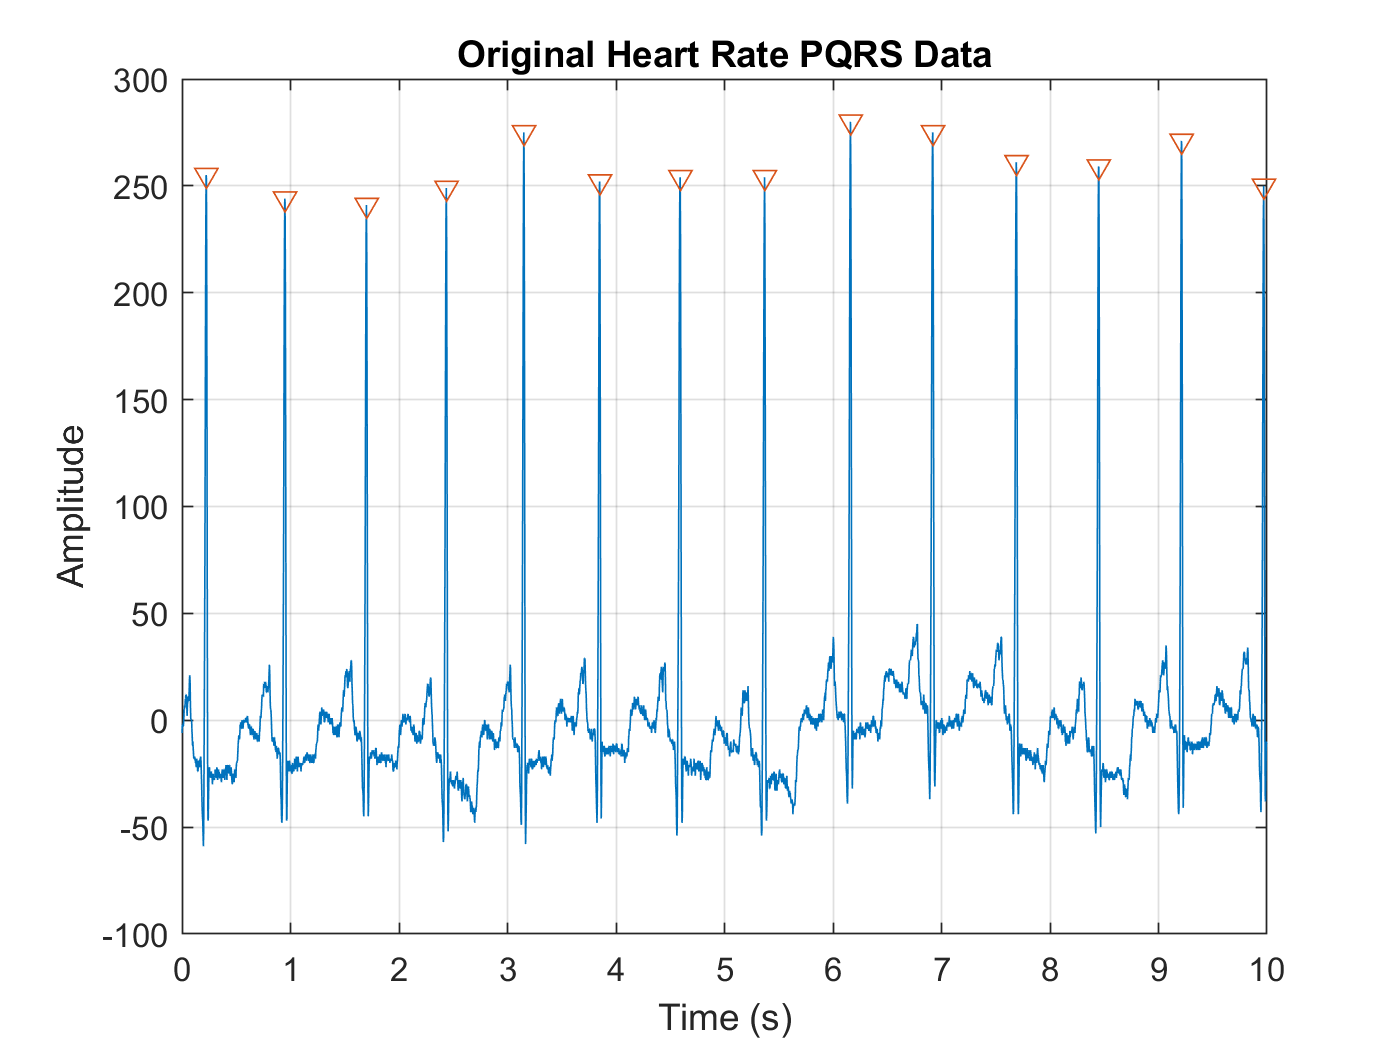

% --Parameters
    sample_freq = 360;              % Sample Frequency (Hz)

% --Load in Data 
    HR_data = load('100m.mat');
    HR_data = HR_data.val;
    
% --Mean Zero Data
    HR_data = HR_data - mean(HR_data);
    
% --Create Time Vector
    time = 0:1/sample_freq:(length(HR_data) - 1)/sample_freq;
    
% --Plot Data
    figure(1)
    plot(time,HR_data);
        hold on
        grid on
        xlabel('Time (s)')
        ylabel('Amplitude')
        title('Original Heart Rate PQRS Data')
        
% --Finding Peaks
    [peaks, int] = findpeaks(HR_data,'MinPeakHeight',150);
    int = int*(1/sample_freq);
    plot(int,peaks,'V')

    
% --Finding carrier frequency
    rate_solution = [];
    
    for i = 1:length(int) - 1
        
        time_difference = (int(i+1)) - (int(i));
        rate = 1/time_difference;
        rate_solution = [rate_solution rate];
        
        
    end
    
    carrier_freq = mean(rate_solution);
    HRV = (std(rate_solution))^2

HRV = 0.0022

    
% --Verify carrier frequency
    heart_rate = carrier_freq * 60;         % Sanity check
    fprintf('Heart Rate is %3.3f',heart_rate)

Heart Rate is 80.112

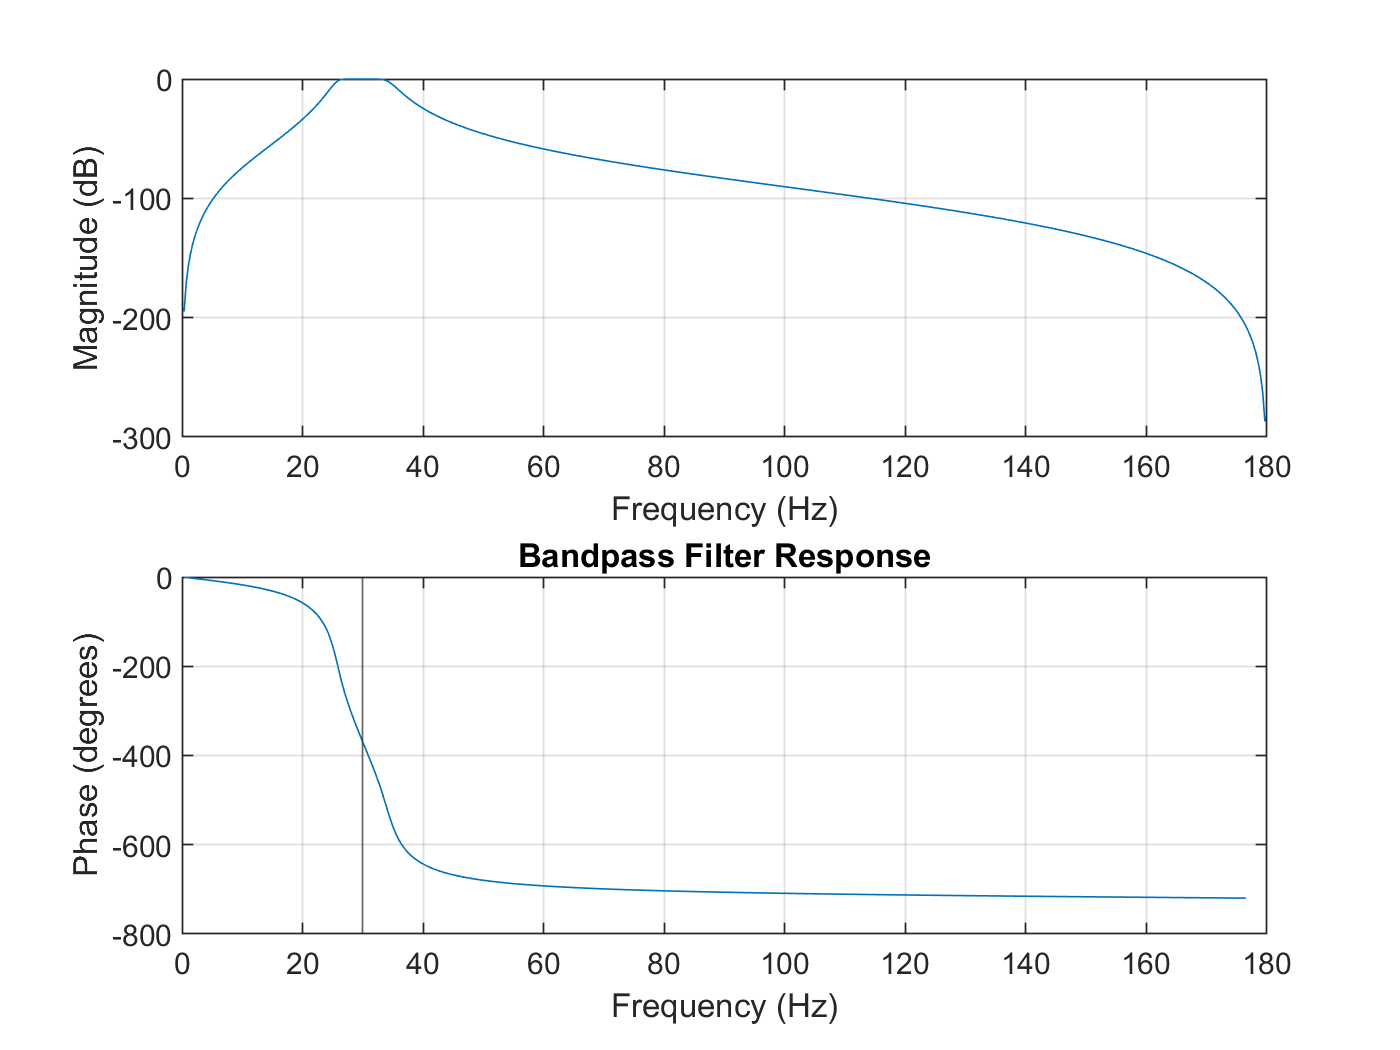

    ten_percent = heart_rate * 0.1;
        
% --Part 1a)
    % --Building a wave to verify process
        f = 30;                      % Frequency (hz)
        w = f*2*pi;                 % Frequency (rad/s)
        amplitude = 1;              % Amplitude
        T = 20;                     % Period of signal (s)
        t = 0:1/sample_freq:T;
        wave = amplitude*sin(w*t);
        N = length(wave);
        
    % --Modulate wave using fmmod()
        wave_modulated = fmmod(wave,f, sample_freq, 25);
        
    % --Plot both
    figure(2)
    subplot(2,1,1)
    plot(t,wave)
        hold on
    plot(t,wave_modulated)
        grid on
        xlim([1 1.2])
        ylabel('Wave Amplitude')
        title('Part 1a) Constructing Modulated Wave')
        subtitle('Original Wave and Modulated Wave')
        
% --Part 1b)
    % --Creating butterworth filter
        freq_bands = [f - 0.15*f , f + 0.15*f];
        freq_band = freq_bands ./ (sample_freq/2);
        [b,a] = butter(4,freq_band,"bandpass");
        
    % --Outputting the frequency response
    figure(3)
    freqz(b,a,[],sample_freq);
        xline(f)
        title('Bandpass Filter Response')
        grid on

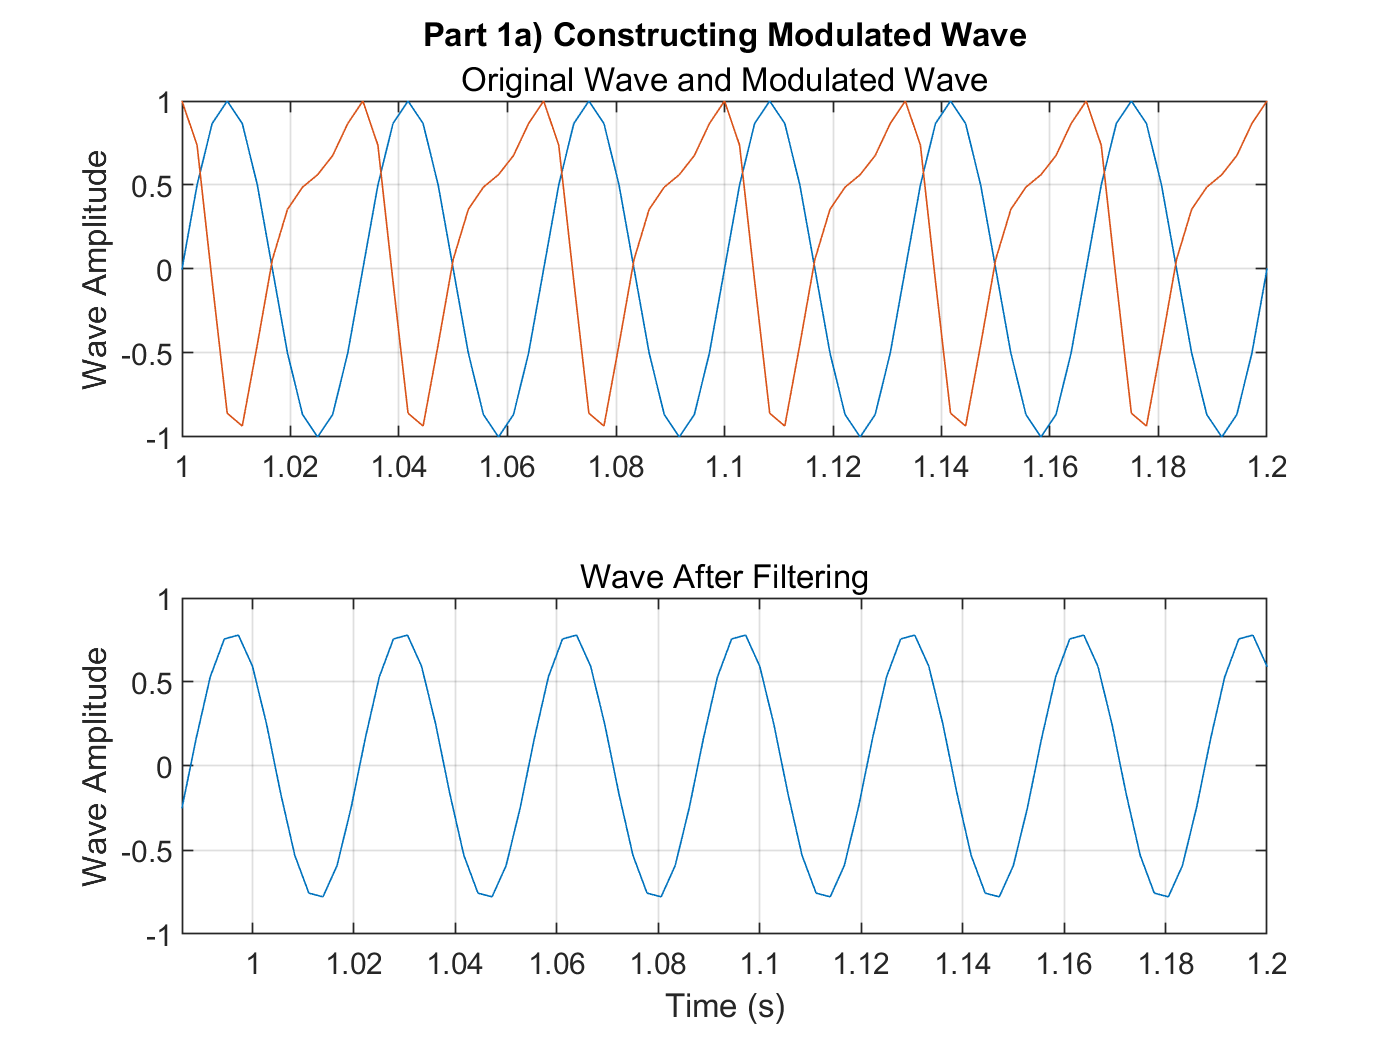

        
    % --Passing the modulated wave through filter
        wave_filtered = filter(b,a,wave_modulated);
        
    % --Outputting final signal
        figure(2)
        subplot(2,1,2)
        plot(t,wave_filtered)
            hold on
            xlim([0.9861 1.2])
            xlabel('Time (s)')
            ylabel('Wave Amplitude')
            subtitle('Wave After Filtering')
            grid on

The filtered signal is not the exact same as the original signal that was created before modulation. This is because of two reasons. The first is there is a smaller wave amplitude at about 0.779 instead of 1, and is also flipped negative. The amplitude is because of the filter roll-offs that are close to the original carrier frequency, so the roll offs will cause some sort of signal attenuation because the bands are tight. This value of 0.779 corresponds with -3dB which is the band-edge roll off attenuation for this filter. The second is the filter phase is roughly -380 degrees at the center frequency. This means that the filtered signal will be shifted which causes the signal shift by about -0.02 as shown in the figure. These changes are the implications that we must deal with when designing the filter. 

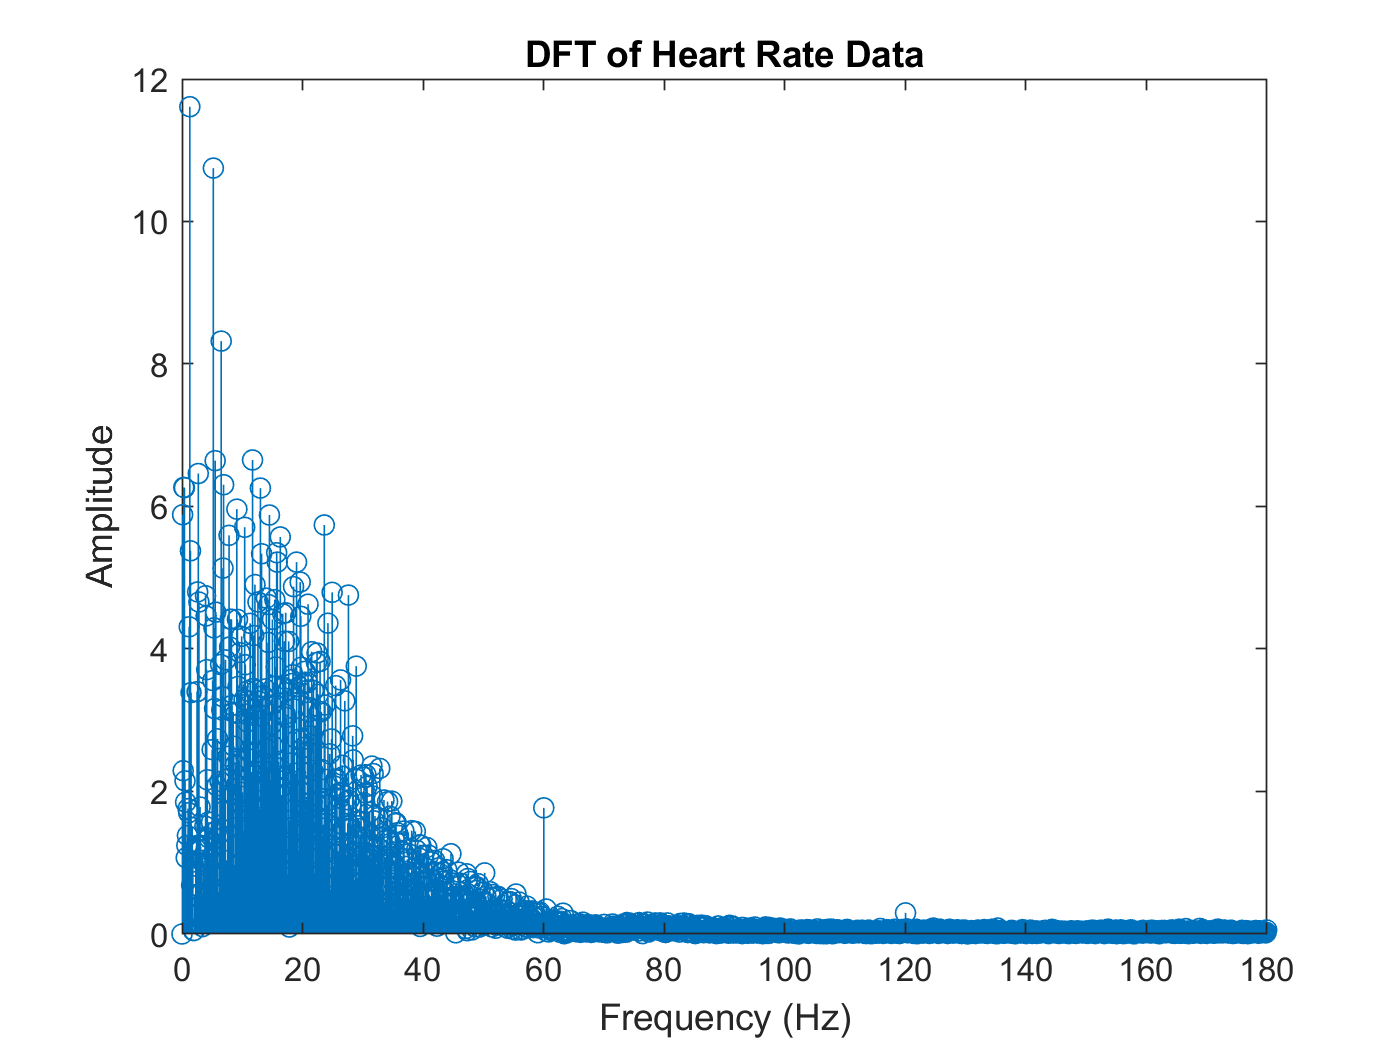

% --Part 1C) Demodulate the heart rate data
    % --Perform FFT on original data
        fft_HR_data = fft(HR_data);
        fft_magnitude = abs(fft_HR_data);
        fft_amplitude = 2*fft_magnitude ./ length(fft_magnitude);
        
    % --Reformatting frequency
        f_vector = (1/max(time))*(0:length(HR_data) - 1);
        
    % --Plot FFT
        figure(4)
        stem(f_vector,fft_amplitude)
            hold on
            xlim([0 sample_freq/2])
            xlabel('Frequency (Hz)')
            ylabel('Amplitude')
            title('DFT of Heart Rate Data')

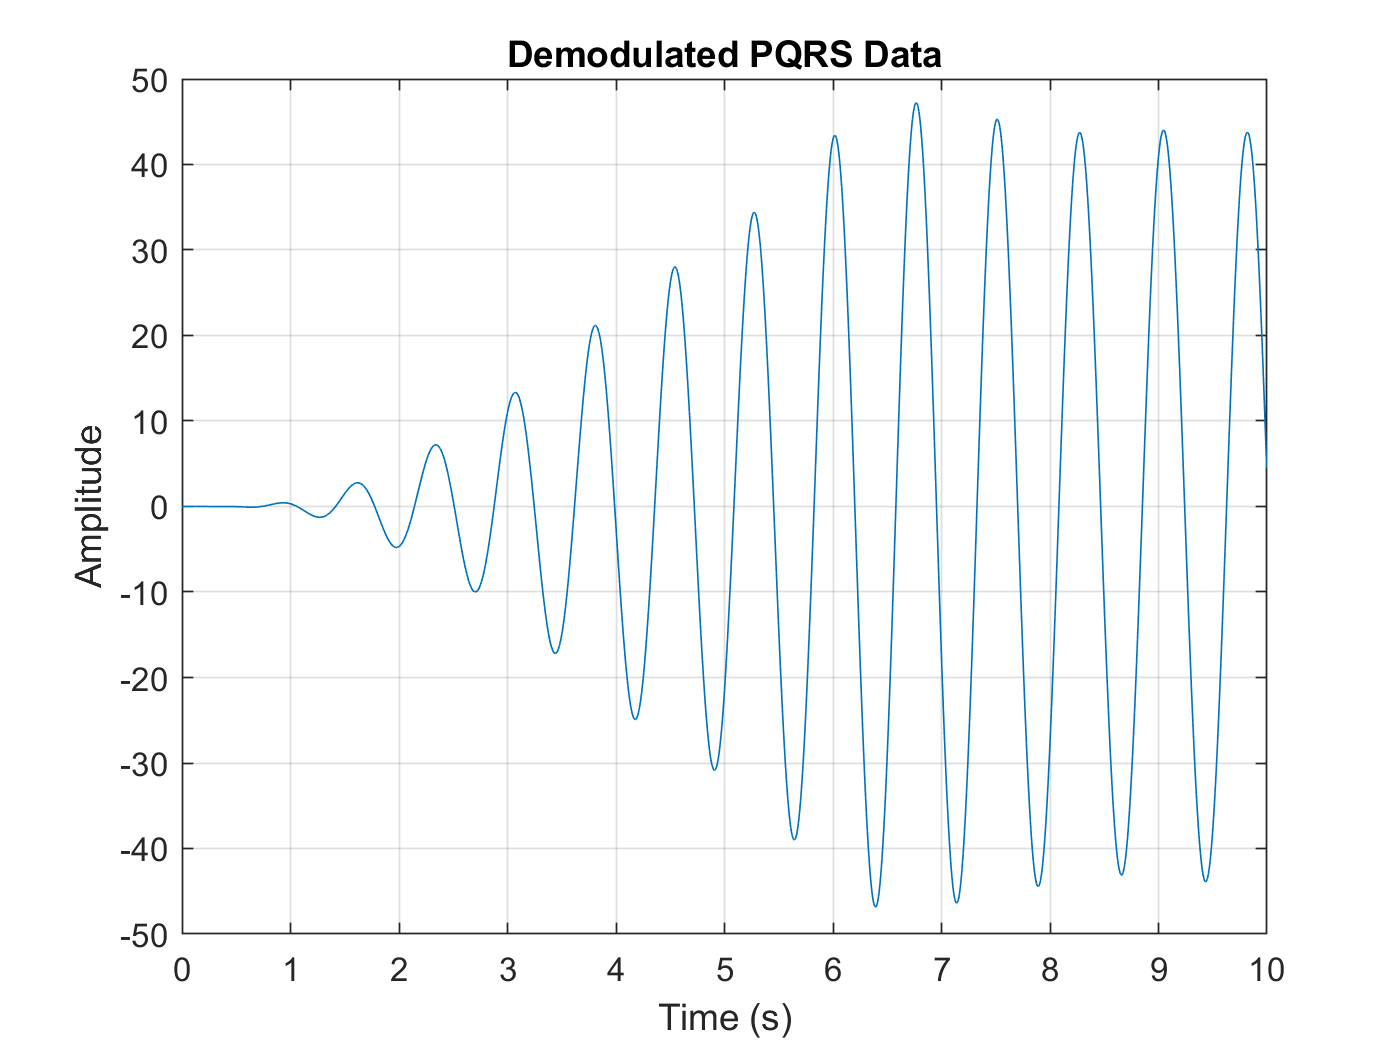

            
    % --Building filter
        freq_band = [carrier_freq - 0.15*carrier_freq, carrier_freq + 0.15*carrier_freq];
        freq_band = freq_band / (sample_freq/2);
        [b,a] = butter(4,freq_band,"bandpass");
        
    % --Passing data through filter
       HR_filtered = filter(b,a,HR_data);
        
    % --Plot out data
        figure(5)
        plot(time, HR_filtered)
            xlabel('Time (s)')
            ylabel('Amplitude')
            grid on
            hold on
            title('Demodulated PQRS Data')

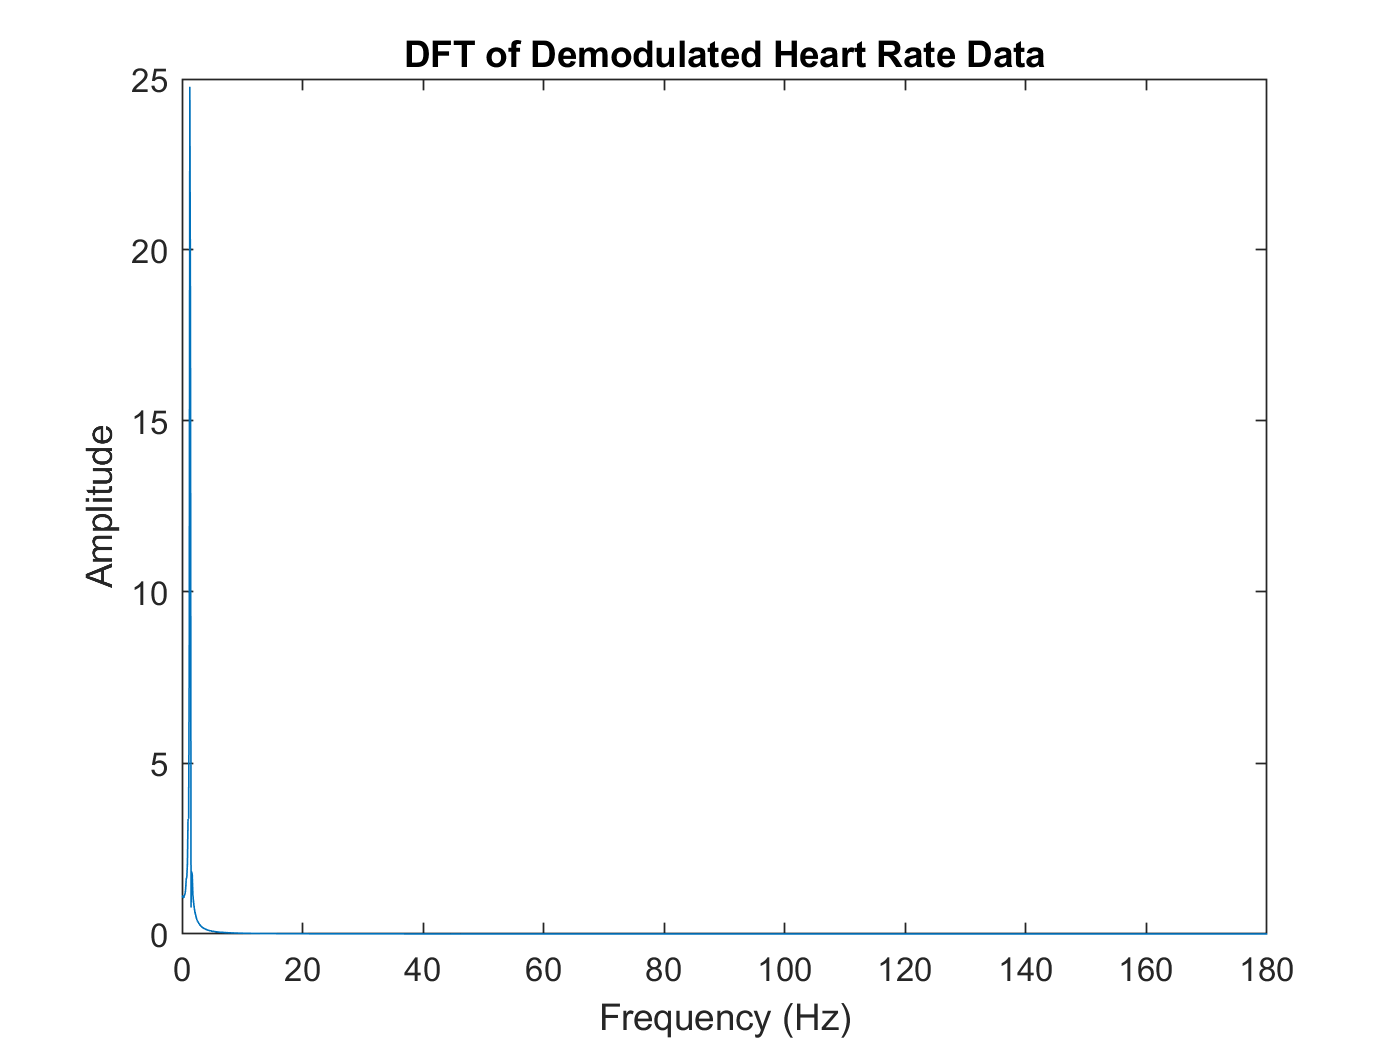

        
    % --Taking FFT and finding the remaining frequency after filtering
        fft_HR_data = fft(HR_filtered);
        fft_magnitude = abs(fft_HR_data);
        fft_amplitude = 2*fft_magnitude ./ length(fft_magnitude);
        
    % --Plot FFT 
        figure(6)
        plot(f_vector,fft_amplitude)
            xlim([0 180])
            xlabel('Frequency (Hz)')
            ylabel('Amplitude')
            title('DFT of Demodulated Heart Rate Data')

        
    % --Finding new demodulated frequency
        [pks, int] = findpeaks(fft_amplitude,'MinPeakHeight',3);
        HR_demodulated = f_vector(int(1));
        
    % --FInding difference in the frequencies
        f_difference = carrier_freq - HR_demodulated;
        Heart_Rate_Variability = f_difference * 1000

Heart_Rate_Variability = 34.8330

This value is within the expected range of a person that is older than 60 years, so my answer makes sense.

## Question 2: Road Image Processing

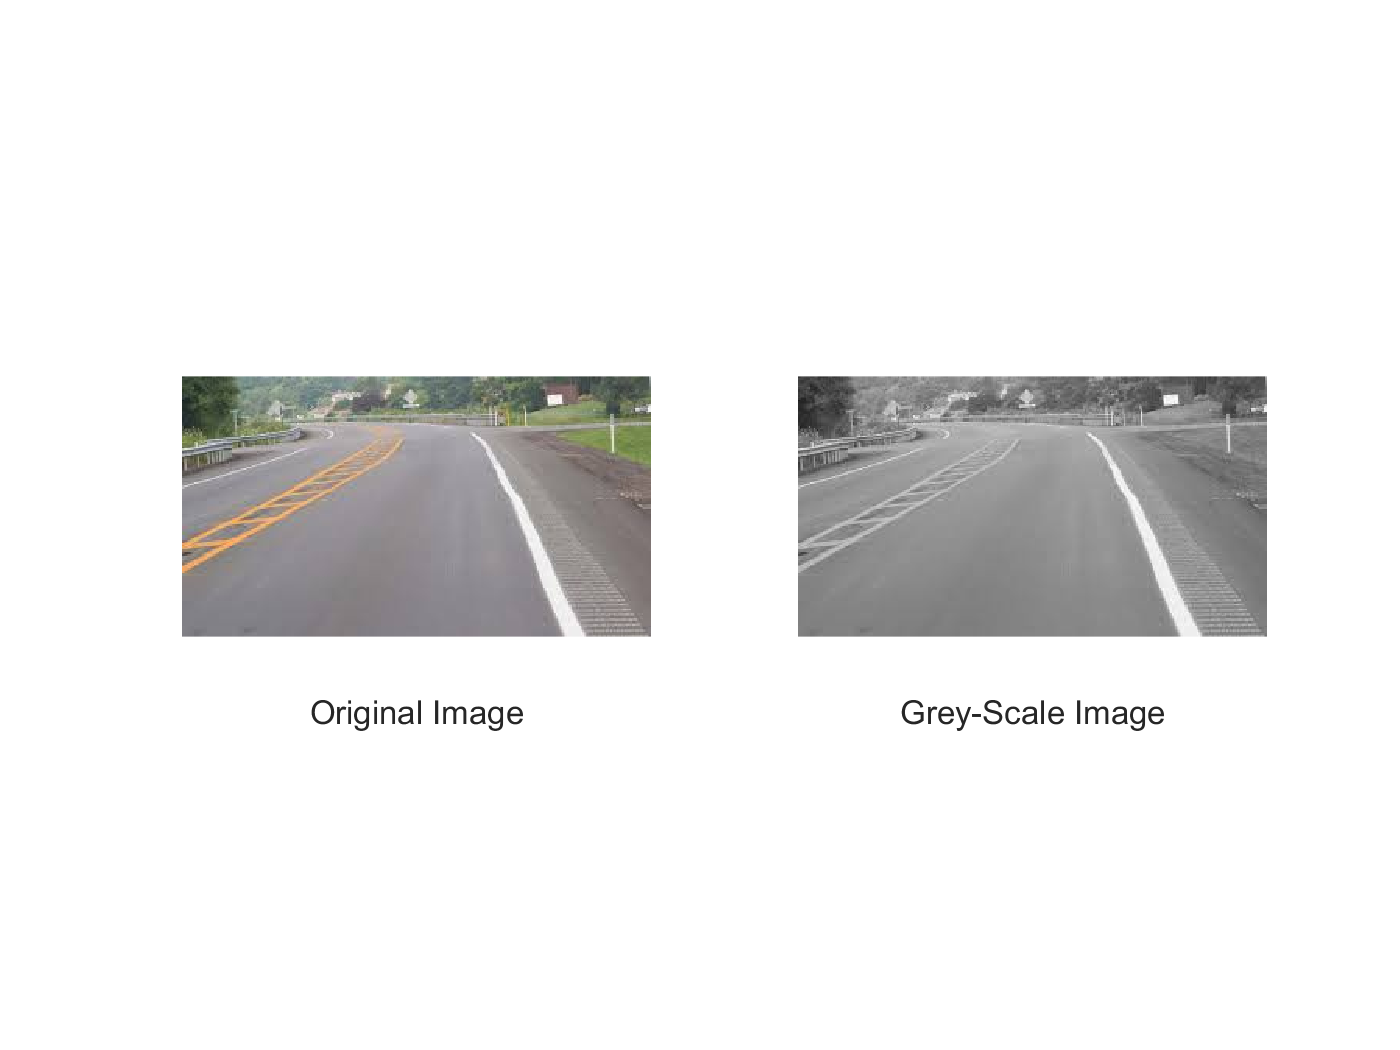

% --Load in image
    RGB_road_image = imread("image 1.jpg");

% --Put image into greyscale
    road_image = im2gray(RGB_road_image);
    
% --Plot Images
    figure()
    title('Original and Grey-Scale Images')
    subplot(1,2,1)                  % Plot RGB images 
    imshow(RGB_road_image)
        xlabel('Original Image')
        
    subplot(1,2,2)
    imshow(road_image)
        xlabel('Grey-Scale Image')

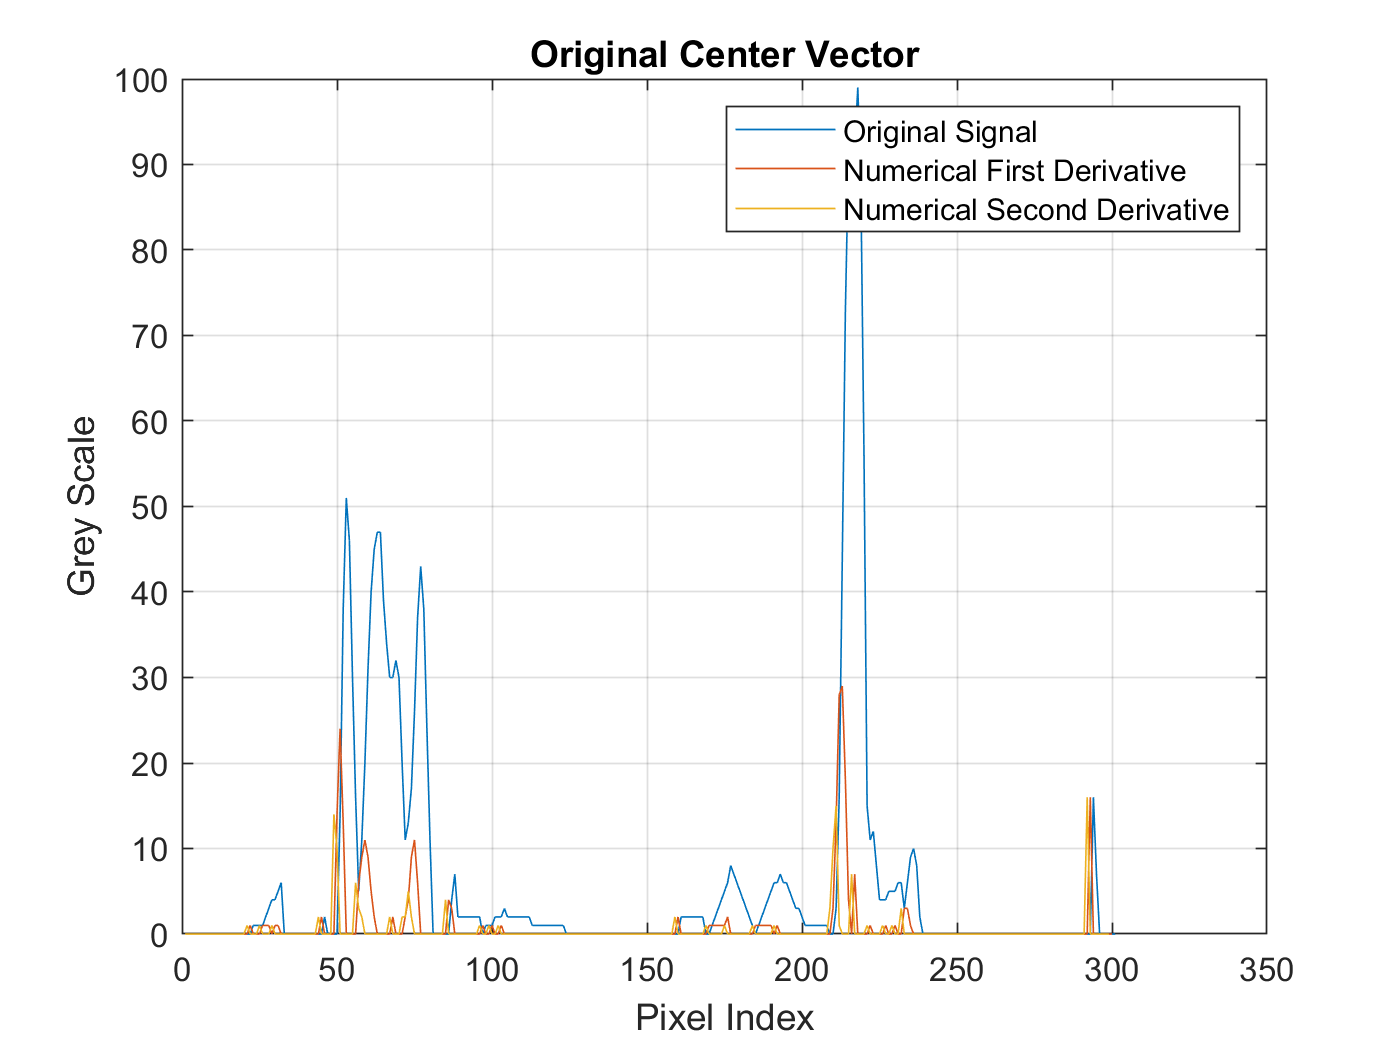

        
% --Selecting Center Row Vector
    center_row_index = floor(height(road_image)/2);
    center_vector = road_image(center_row_index,:);
    center_vector = center_vector - mean(center_vector);
    
% --Plotting
    figure()
    plot(center_vector)
        hold on
        grid on
        xlabel('Pixel Index')
        ylabel('Grey Scale')
        title('Original Center Vector')
        
% --Taking derivative spatially
    y = diff(center_vector);
        plot(y)
        
    yy = diff(y);
        plot(yy)
        legend('Original Signal','Numerical First Derivative','Numerical Second Derivative')

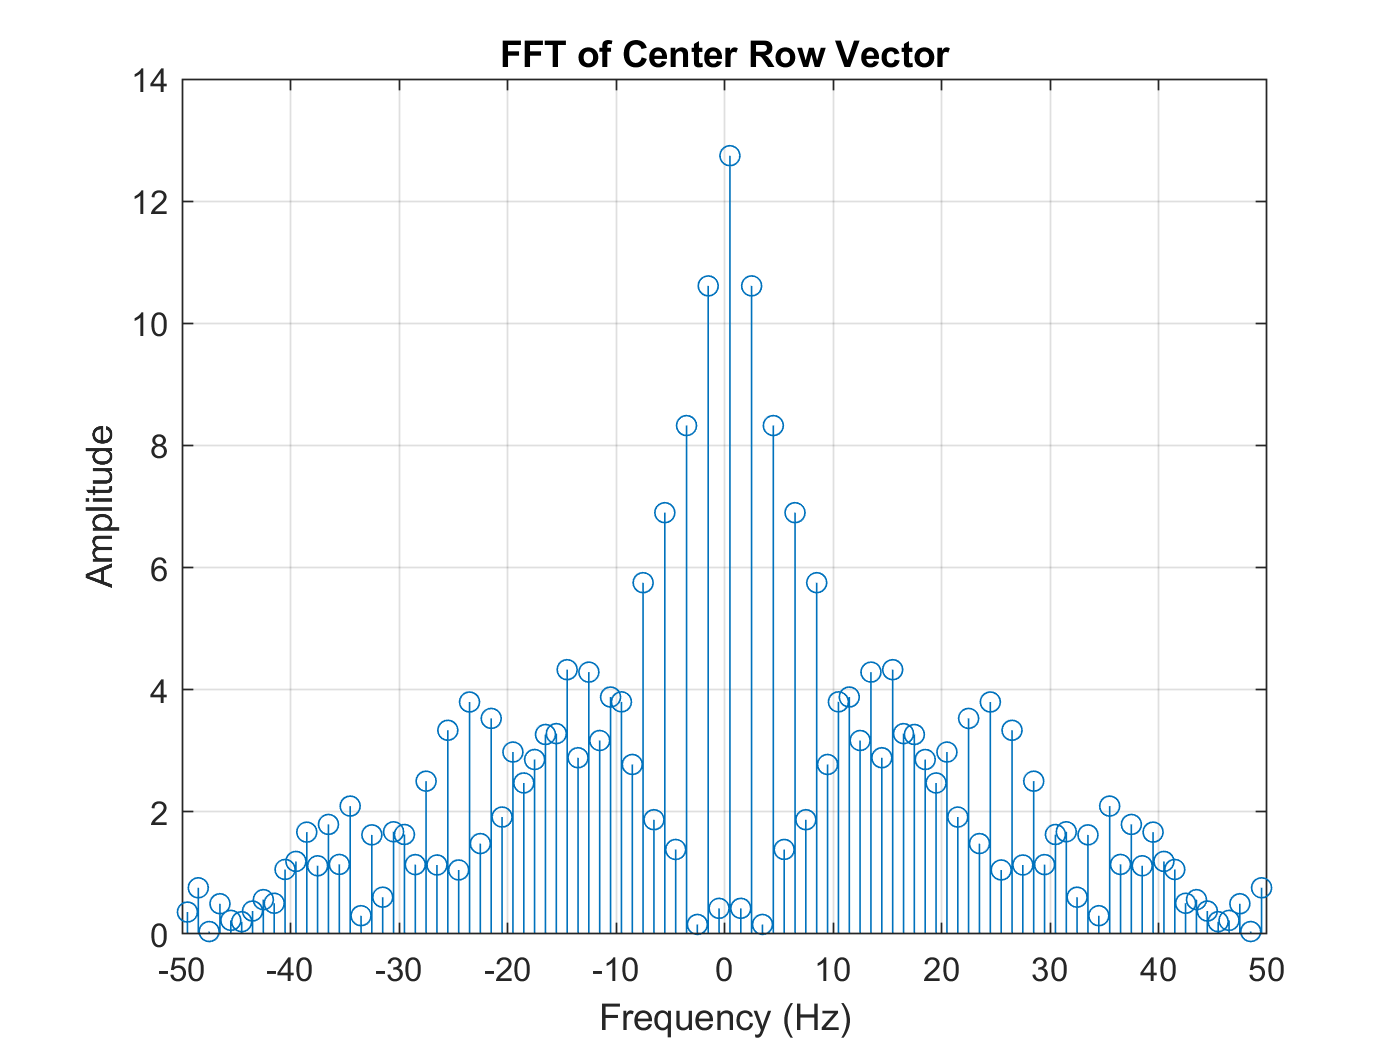

    
% --Taking FFT
    fft_center = fft(center_vector);
    fft_center_mag = abs(fft_center);
    fft_center_amp = 2*fft_center_mag ./ length(fft_center);
    
% --Formatting frequency
    N = length(center_vector);
    frequency_unshifted = (-N/2) : (N/2) - 1;
    frequency = fftshift(frequency_unshifted);
    
% --Plotting FFT
    figure()
    stem(frequency, fft_center_amp)
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        title('FFT of Center Row Vector')
        hold on
        grid on
        xlim([-50 50])

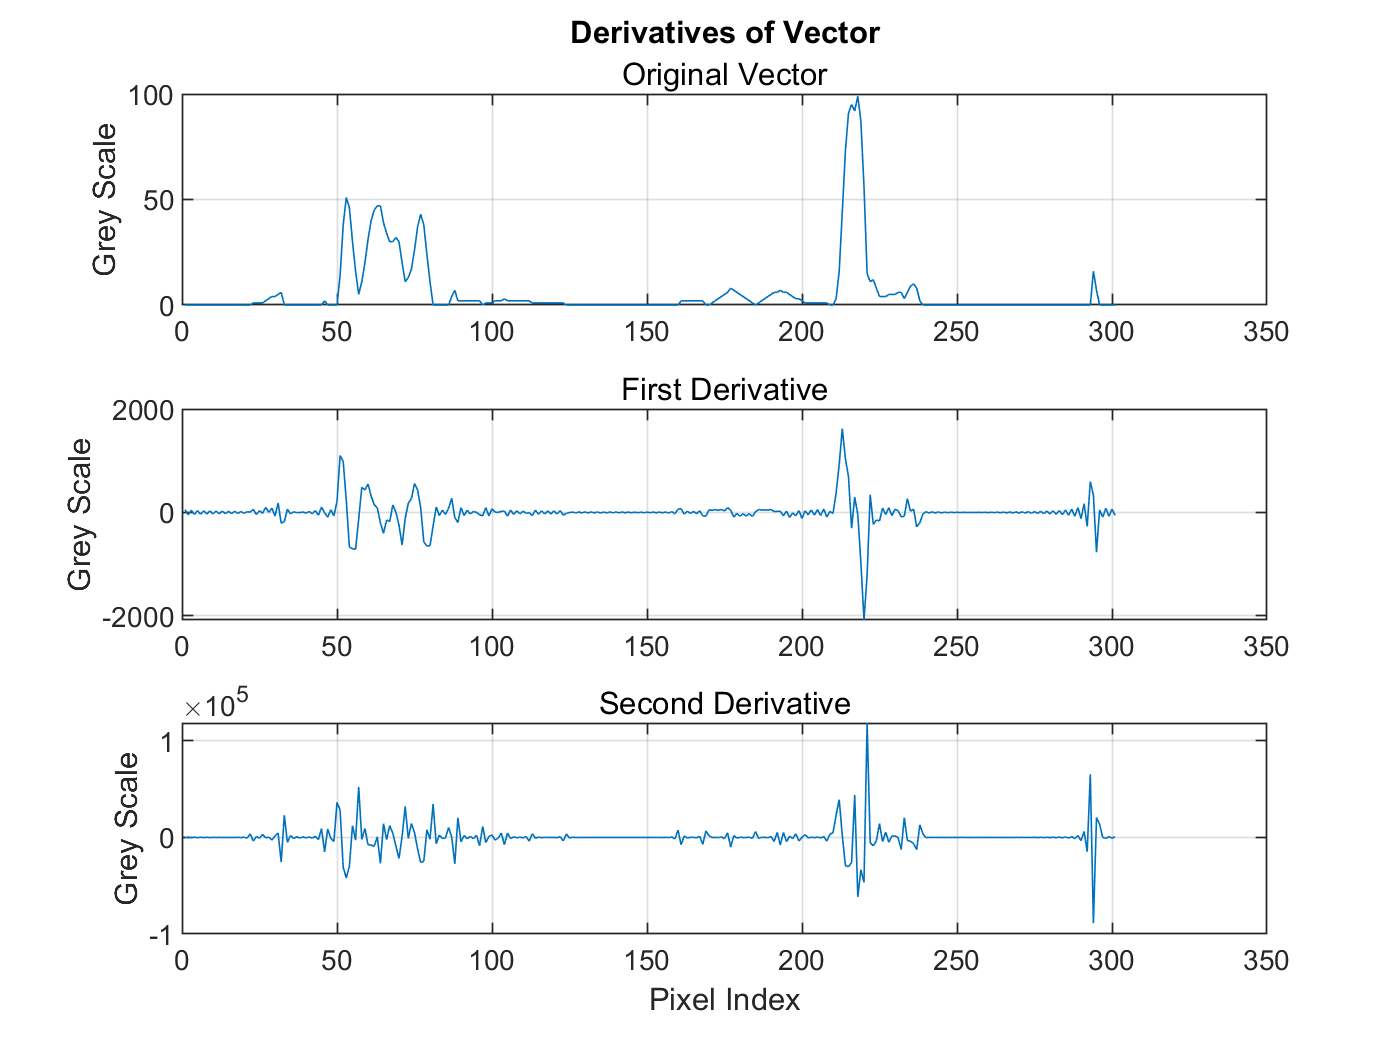

        
% --Finding derivative of vector
    dfft_center = 1i * frequency .* fft_center;
    dfft_center_mag = abs(dfft_center);
    dfft_center_amp = 2* dfft_center_mag ./ (N);
    
% --Finding second derivative
    ddfft_center = 1i * frequency .* dfft_center;
    ddfft_center_mag = abs(ddfft_center);
    ddfft_center_amp = 2* ddfft_center_mag ./ (N.^2);
    
% --Taking inverse FFT
    dcenter_vector = real(ifft(dfft_center));
    ddcenter_vector = real(ifft(ddfft_center));
    
% --Plot
    figure()
    subplot(3,1,1)
    plot(center_vector)
        hold on
        grid on
        subtitle('Original Vector')
        ylabel('Grey Scale')
        title('Derivatives of Vector')
    subplot(3,1,2)
    plot(dcenter_vector)
        subtitle('First Derivative')
        grid on
        ylabel('Grey Scale')
    
    subplot(3,1,3)
    plot(ddcenter_vector)
        subtitle('Second Derivative')
        grid on
        ylabel('Grey Scale')
        xlabel('Pixel Index')

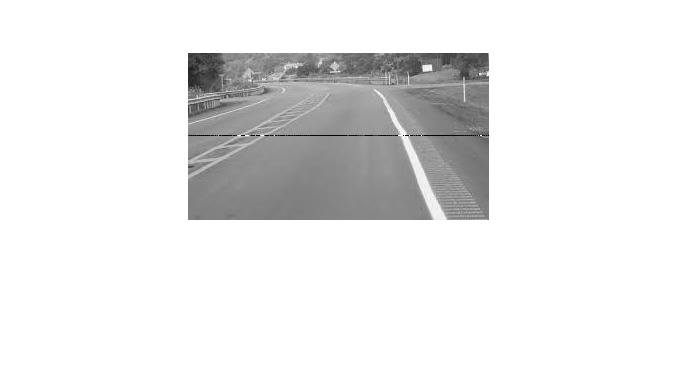

        
% --Inputting back into image
    figure()
    road_image(center_row_index,:) = dcenter_vector;
    imshow(road_image)

After taking the derivative of the center row vector it appears as if it is off by a scaling factor but the peaks appear in the same place. The derivatives also make sense, meaning that there are negative derivatives when there is a negative slope in our original vector. This could still be useful for purposes of edge detection algorithms because the spikes still occur at the right spots indicating the edges are detected in the right place.

## Question 3: Image Filtering

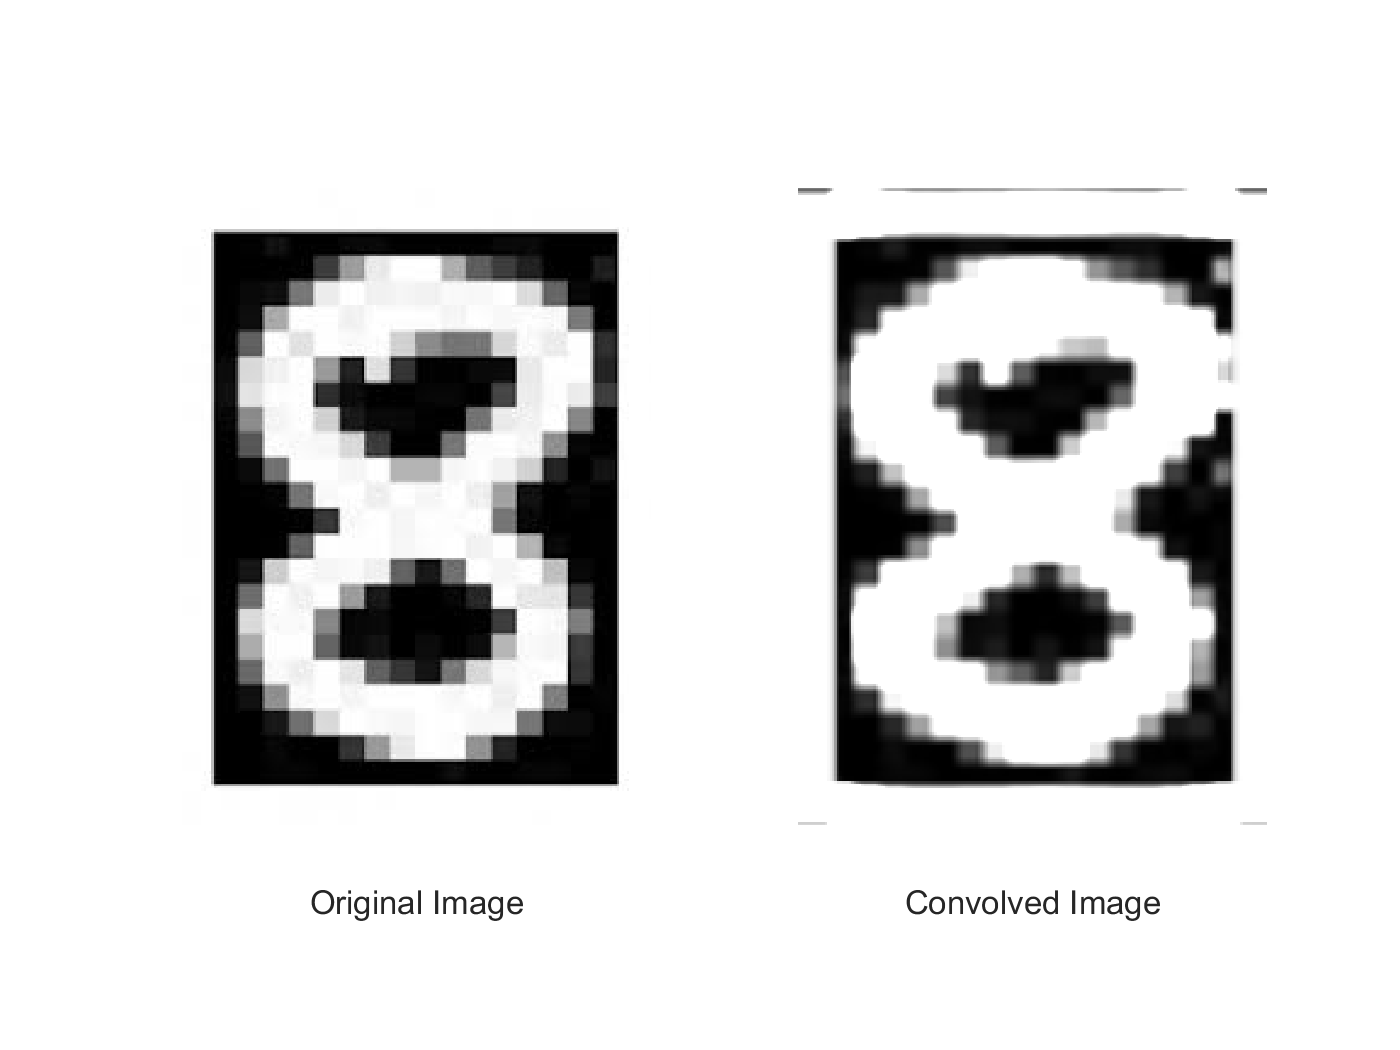

% --Load in image
    fig_8 = imread('image 2.jpg');
    fig_8_gray = im2gray(fig_8);
    
% --Plot Images
    figure()
    title('Original and Grey-Scale Images')
    subplot(1,2,1)                  % Plot RGB images 
    imshow(fig_8_gray)
        xlabel('Original Image')
        
% --Create the smoothing matrix
    smoothing_matrix = ones(5,5);
    
% --Convolve image with smoothing matrix
    convolved_8 = conv2(fig_8_gray, smoothing_matrix);
    convolved_8 = convolved_8 ./ mean(convolved_8);
    
% --Resize image after convolution
    N1 = length(smoothing_matrix) - 1;
    M1 = width(smoothing_matrix) - 1;
    N2 = length(fig_8_gray);
    M2 = width(fig_8_gray);
    convolved_8 = convolved_8((N1/2):(N2 + 1), (M1/2):(M2 + 1) );  % [CHANGE SIZE]
    
% --Output convolved image
    subplot(1,2,2)                 
    imshow(convolved_8)
        xlabel('Convolved Image')

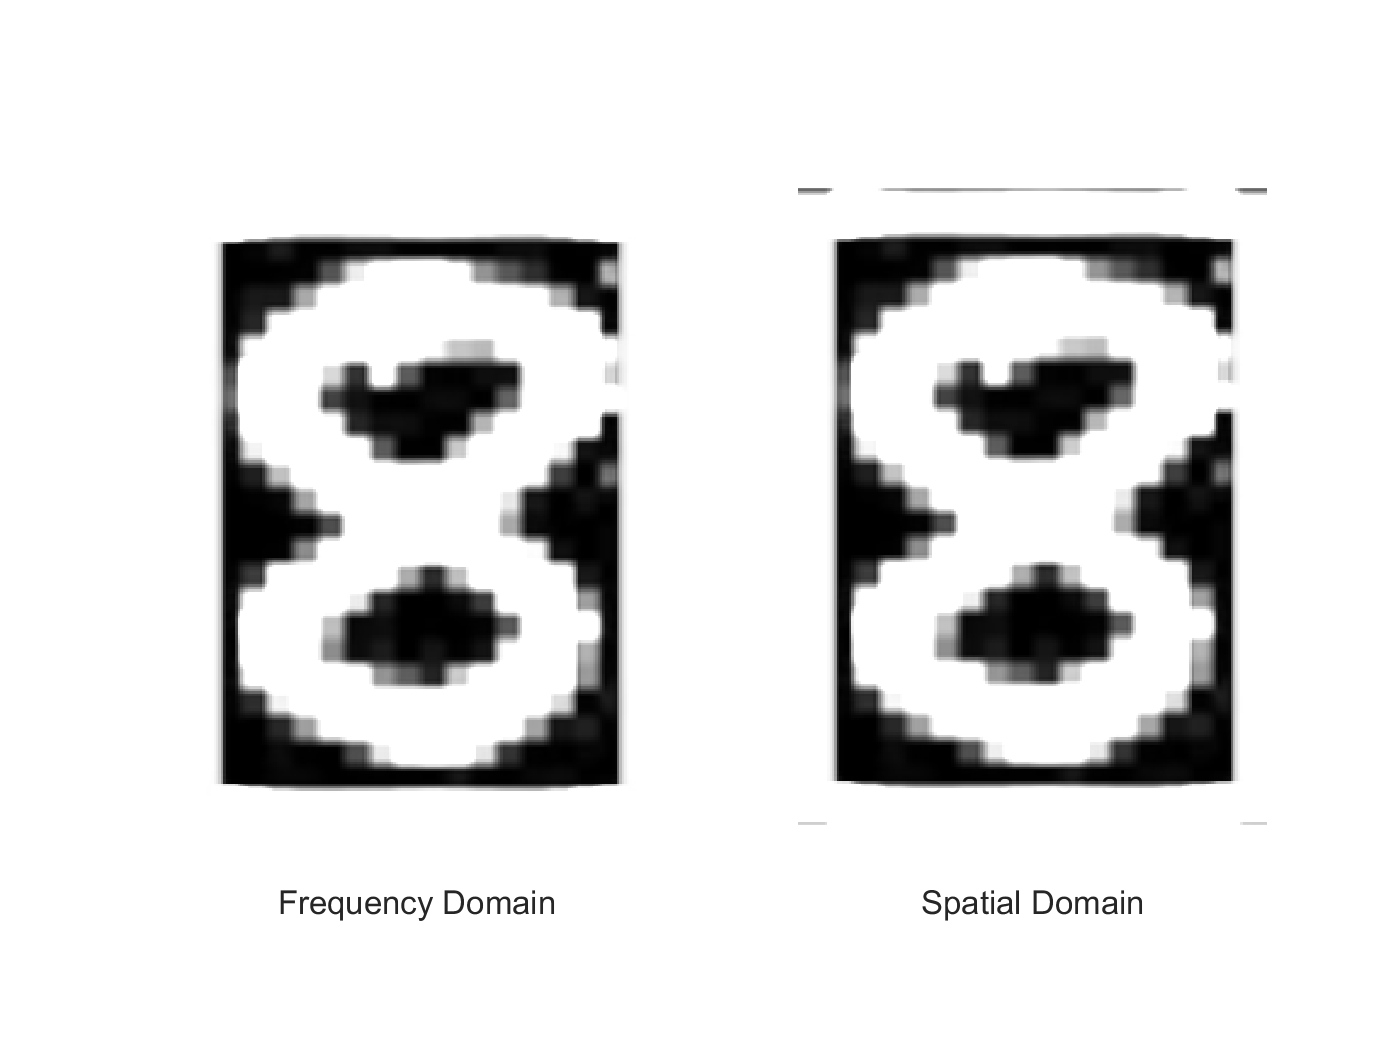

        
% --Zero-pad to have the same size
    zero_length = zeros(N2 - length(smoothing_matrix), width(smoothing_matrix));
    smoothing_matrix = [smoothing_matrix; zero_length];
    zero_width = zeros(N2, M2 - width(smoothing_matrix));
    smoothing_matrix = [smoothing_matrix,zero_width];
    
% --Convert to frequency domain
    fft_fig_8 = fft2(fig_8_gray);
    fft_smooth = fft2(smoothing_matrix);
    
% --Multiply two together
    fft_fig_8_smooth = fft_fig_8 .* fft_smooth;
    
% --Inverse FFT
    fig_8_smooth = ifft2(fft_fig_8_smooth);
    fig_8_smooth = fig_8_smooth ./ mean(fig_8_smooth);
    % fig_8_smooth = uint8(fig_8_smooth);
    
% --Output figure
    figure()
    subplot(1,2,1)
    imshow(fig_8_smooth)
        xlabel('Frequency Domain')
        
    subplot(1,2,2)
    imshow(convolved_8)
        xlabel('Spatial Domain')

    From the two methods used to smooth the image, both create the same image with the figure eight. The key difference lies with the math of the convolution, particularly with the edges of the image. Because when the convolution is taken we increaes the size of the image it needs to be resized to maintain the original image size. The convolution also adds black borders at the top and bottom. Both images are smoothed the same way.